   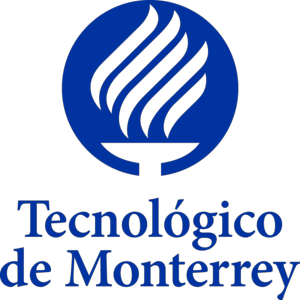

**                Diseño de la zona de curvas en una pista de Fórmula Uno **

**Profesor**    

Omar Said Buassi Monroy

**Equipo 1**

**Javier Eric Hernández A01635390**

**Armando Terrazas Gómez A01640924**

**Isaac Ramírez Robles Castillo A01635018**

**Samuel García Berenfeld A0164**

**Modelación computacional aplicando leyes de conservación **

**(Gpo 6)**

**Tecnológico de Monterrey Campus Guadalajara**

02 de Diciembre del 2021

## **Reto: **

Conociendo que la empresa encargada de la construcción de la pista necesita información referente al trazado de la zona de curvas y el calor generado en la misma zona, se plantea el reto de determinar la ubicación de las gradas en un lugar seguro para los espectadores y garantizando un excelente punto de observación en este deporte. Para ello se deberá presentar la simulación de un auto (punto) al correr por la pista en la zona de rectas y en la zona de curvas propuesta realizando dos simulaciones, una que siga por la pista y otra que se salga de la pista.

Conscientes de las diversas etapas que incluyen la decisión de la ubicación de las gradas, es importante para la empresa contar con toda la información referente a la zona de curvas de la pista y el calor que se irá absorbiendo. 

Para satisfacer esta necesidad se le solicita al equipo preparar una entrega para el departamento de Construcción y Seguridad que incluya (Específico)  dos simulaciones del desplazamiento de un carro al entrar a la zona de curvas: en uno se observará la salida del auto de la pista pero sin chocar con la grada propuesta para el público, misma que será ubicada por el equipo cumpliendo los requisitos de seguridad y en la segunda se observará la continuación del coche de carreras en la pista sin percance. (Medible y alcanzables)  

Ambas simulaciones deberán desplegar en pantalla, el nivel de cantidad de energía mecánica, en Joules, que se convirtió en Calor durante el recorrido. Sus cálculos deben estar reportados paso a paso y cuidadosamente fundamentados, explicando cómo tomaron en cuenta en su estimación los valores numéricos de la fricción, la curvatura del recorrido, y cómo pueden argumentar que su estimación estará cercana al valor real.

## **Planteamiento:**

Para obtener los coeficientes de la función cúbica utilizamos el Método de Determinantes: 

Primero obtuvimos cuáles son las coordenadas (x,y) de los extremos de la pista que debemos conectar. Luego, obtuvimos 2 puntos cercanos a estos puntos para poder obtener la pendiente de la recta tangente a los extremos de la pista.

Queremos que la curva que pase entre estos 2 puntos sea similar a una función cúbica, por lo que tendremos que buscar cuál es la ecuación cúbica que cruza por estos 2 extremos de la pista que buscamos unir. Usaremos la ecuación y=a3x^3 + a2x^2 + a1x +a0. 

Conocemos 2 coordenadas (x,y) para sustituir en la ecuación, lo que no conocemos son los coeficientes C3, C2, C1 y C0. Ya conocemos 2 ecuaciones entonces, y tenemos 4 variables. 

Otra ecuación que podemos encontrar es la derivada a esta función cúbica y esta es igualada a la pendiente de la recta tangente en los 2 extremos de la pista. Esta ecuación es: dy/dx = 3*C3*x^2 + 2*C2*x + C1 + 0.

Las pendientes a la recta tangente se calculan con los 2 puntos cercanos a los extremos, usando la fórmula m = y2-y1 / x2-x1.

Ahora tenemos ya 4 ecuaciones y 4 variables, podemos usar el método de determinantes para descubrir el valor de los 4 coeficientes. 

**Longitud de Curva**

Para obtener la longitud de curva, utilizamos la fórmula anexada. Lo que hace es dividir la curva en segmentos y sumarlos usando la integral. Esta longitud de curva sirve para confirmar que la pista diseñada es menor a una pista normal.


$$\int_a^b \sqrt{1+{\left\lbrack f^{\prime } \left(x\right)\right\rbrack }^2 }\textrm{dx}$$


**Investigación sobre el radio de curvatura:**

El radio de curvatura se puede concebir como un valor perteneciente a una función que nos muestra la circunferencia tangente a cada punto de una curva (entendiendo a esa línea tangente como la normal del radio de la llamada "circunferencia osculatriz). Como este círculo es tangencial a la curva, su derivada en el punto coincide con la derivada de la función, la ecuación para obtener este radio, generada por Bernoulli, es la siguiente:

Podemos ver que depende de las derivadas tanto respecto a x como respecto a y de nuestra función original, y encuentra dicho radio en cada punto. El signo negativo se omite al final, ya que se entiende convencionalmente que el radio de curvatura es un valor positivo o cero.

Para ecuaciones que se pueden escribir en la forma F(x)=y el radio se determina con:

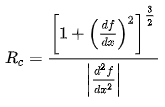

(Soto, s.f.)

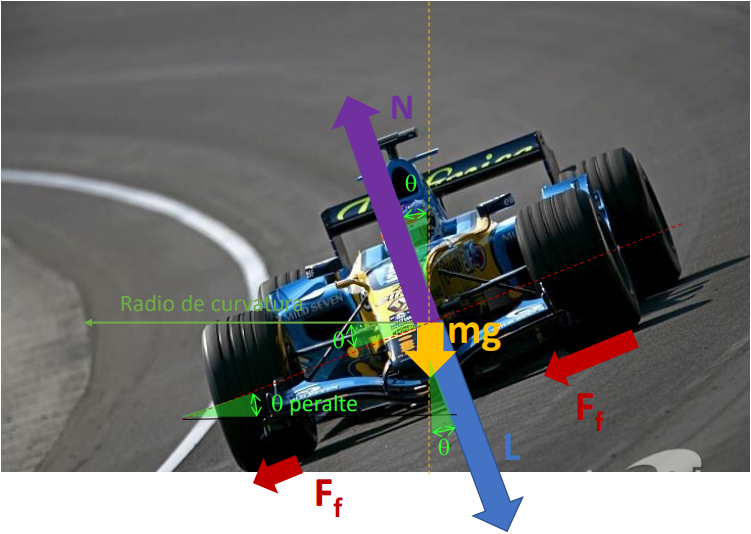

**Trabajo conservativo y no conservativo**

Respecto a la discusión que tuvimos sobre las fuerzas llegamos a las siguientes conclusiones:

- Trabajo conservativo: Fuerza centrípeta

La sumatoria de fuerzas en dirección del radio es igual a la masa por la aceleración centrípeta $\sum F_c =-m*a_c$  lo que permite desplazar al vehículo sobre la pista a gran velocidad dando un impulso por parte de la pista hacia las llantas provocado por la fricción.

- Trabajo no conservativo: fricción, L (downforce)

La downforce es la fuerza que mantiene al vehículo sujeto a la superficie mejorando su aerodinámica dando así la oportunidad de ir más rápido.

Esta fuerza es función de la velocidad


$$\sum F_y =-\mathrm{mg}-L+N=0$$


- No realizan trabajo: Normal y mg

La fuerza normal también actúa sobre el eje y es por eso que se le resta a la ecuación pasada, dentro de esta fuerza podemos encontrar dos ecuaciones una siendo la radial $N\mu_s =-\mathrm{mg}-L+N=0$ y la otra la vertical $N=\mathrm{mg}+L$

El coeficiente de fricción estático $\mu_s$ determina el valor máximo que puede tener la fricción antes de derrapar. 


$$\left(\mathrm{mg}+L\left(v\right)\right)\mu_s =m*\frac{{v^2 }_t }{R}$$


(velocidad tangencial) 

Al tener este valor de fricción podemos calcular el valor máximo de velocidad en una curva despejando esta ecuación.

**Método de Euler:**

## Pistas escogidas:

**Europa:**

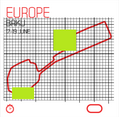

**Italia:**

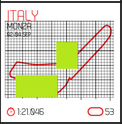

**Bélgica**

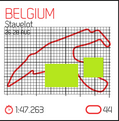

clc
clearvars
menu=0;

Menú para seleccionar la pista:

while menu ~= 7
    fprintf("\nSegmentos de Pista:\n\t1. Europa 1\n\t2. Europa 2\n\t3. Bélgica 1\n\t4. Bélgica 2\n\t5. Italia 1\n\t6. Italia 2\n\t7. Salir\n")
    menu=input("Ingresa el número correspondiente: ");
    
    if menu == 1
        %Europa 1
        titulo = "Europa | Segmento 1";
        x1 = (21/10)*25.1*(10^-3)*16583;
        y1 = (17/10)*25.1*(10^-3)*16583;
        x3 = (20/10)*25.1*(10^-3)*16583;
        y3 = (16/10)*25.1*(10^-3)*16583;
        x2 = (28/10)*25.1*(10^-3)*16583;
        y2 = (22.5/10)*25.1*(10^-3)*16583;
        x4 = (26/10)*25.1*(10^-3)*16583;
        y4 = (23/10)*25.1*(10^-3)*16583;
        angle = 50;
        complementary = 40;
        Punto_1 = [950,760];
        Punto_2 = [Punto_1(1)+80*cosd(angle),Punto_1(2)+80*sind(angle)];
        Punto_3 = [Punto_1(1)+40*cosd(-complementary),Punto_1(2)+40*sind(-complementary)];
        Punto_4 = [Punto_2(1)+40*cosd(-complementary),Punto_1(2)+40*sind(angle)];
        
        coordenadasX = [Punto_1(1),Punto_2(1),Punto_4(1),Punto_3(1)];
        coordenadasY = [Punto_1(2),Punto_2(2),Punto_4(2),Punto_3(2)];

    elseif menu==2
        %Europa 2
        titulo = "Europa | Segmento 2";
        x1 = (15/10)*25.1*(10^-3)*16583;
        y1 = (13/10)*25.1*(10^-3)*16583;
        x3 = (14/10)*25.1*(10^-3)*16583;
        y3 = (13/10)*25.1*(10^-3)*16583;
        x2 = (24/10)*25.1*(10^-3)*16583;
        y2 = (10/10)*25.1*(10^-3)*16583;
        x4 = (25/10)*25.1*(10^-3)*16583;
        y4 = (10.1/10)*25.1*(10^-3)*16583;
        
        angle = 50;
        complementary = 40;
        Punto_1 = [675,520];
        Punto_2 = [Punto_1(1)+80*cosd(angle),Punto_1(2)-80*sind(-angle)];
        Punto_3 = [Punto_1(1)+40*cosd(complementary),Punto_1(2)+40*sind(-complementary)];
        Punto_4 = [Punto_2(1)+40*cosd(-complementary),Punto_1(2)+40*sind(-angle)];
        
        coordenadasX = [Punto_1(1),725,690,650];
        coordenadasY = [Punto_1(2),500,492.5,510];
            
    elseif menu==3
        %Belgica 1
        titulo = "Bélgica | Segmento 1";
        x1 = (13/10)*25.1*(10^-3)*16583;
        y1 = (6.57/10)*25.1*(10^-3)*16583;
        x3 = (12/10)*25.1*(10^-3)*16583;
        y3 = (6.5/10)*25.1*(10^-3)*16583;
        x2 = (24/10)*25.1*(10^-3)*16583;
        y2 = (6/10)*25.1*(10^-3)*16583;
        x4 = (25/10)*25.1*(10^-3)*16583;
        y4 = (5/10)*25.1*(10^-3)*16583;
            
        
        
        coordenadasX = [900,960,910,850];
        coordenadasY = [290,255,235,260];
    elseif menu==4
        %Belgica 2
        titulo = "Bélgica | Segmento 2";
        x1 = (26/10)*25.1*(10^-3)*16583;
        y1 = (10/10)*25.1*(10^-3)*16583;
        x3 = (25/10)*25.1*(10^-3)*16583;
        y3 = (10.2/10)*25.1*(10^-3)*16583;
        x2 = (31/10)*25.1*(10^-3)*16583;
        y2 = (5/10)*25.1*(10^-3)*16583;
        x4 = (32/10)*25.1*(10^-3)*16583;
        y4 = (4.5/10)*25.1*(10^-3)*16583;
            
        
        coordenadasX = [1080,1170,1145,1050];
        coordenadasY = [360,270,220,310];
    elseif menu==5
           
        %Italia 1
        titulo = "Italia | Segmento 1";
        x1 = (2.5/10)*25.1*(10^-3)*16583;
        y1 = (5/10)*25.1*(10^-3)*16583;
        x3 = (1/10)*25.1*(10^-3)*16583;
        y3 = (6/10)*25.1*(10^-3)*16583;
        x2 = (17/10)*25.1*(10^-3)*16583;
        y2 = (0.5/10)*25.1*(10^-3)*16583;
        x4 = (18/10)*25.1*(10^-3)*16583;
        y4 = (1.2/10)*25.1*(10^-3)*16583;
            
        coordenadasX = [150,235,200,120];
        coordenadasY = [150,70,50,125];
    else 
        %Italia 2
        titulo = "Italia | Segmento 2";
        x1 = (20/10)*25.1*(10^-3)*16583;
        y1 = (11/10)*25.1*(10^-3)*16583;
        x3 = (19/10)*25.1*(10^-3)*16583;
        y3 = (11/10)*25.1*(10^-3)*16583;
        x2 = (25/10)*25.1*(10^-3)*16583;
        y2 = (19/10)*25.1*(10^-3)*16583;
        x4 = (26/10)*25.1*(10^-3)*16583;
        y4 = (16/10)*25.1*(10^-3)*16583;
        
        coordenadasX = [850,915,880,825];
        coordenadasY = [520,710,730,570];
    end
    if menu >0 && menu<7
        lineas=input("¿Quieres ver las líneas tangentes a 10 puntos en la pista? (sí=1, no=2): ");
        if x2>x1
            xmax=x2;
            xmin=x1;
            ymax=y2;
            ymin=y1;
        else
            xmax=x1;
            xmin=x2;
            ymax=y1;
            ymin=y2;
        end
        
        if y2>y1
            xloc=x2;
            yloc=y2;
        else
            xloc=x1;
            yloc=y1;
        end
        

Cálculo de coeficientes para función cúbica.

        m1 = (y3-y1)/(x3-x1);
        m2 = (y4-y2)/(x4-x2);
        
        ecuacion1 = [x1^3,x1^2,x1,1; 
                     x2^3,x2^2,x2,1; 
                     3*x1^2,2*x1,1,0; 
                     3*x2^2,2*x2,1,0];
        
        resultados = [y1;y2;m1;m2];
        
        m = det(ecuacion1);
        
        ecuacionC3 = ecuacion1;
        ecuacionC3(:,1) = resultados;
        C3 = det(ecuacionC3)/m;
        
        ecuacionC2 = ecuacion1;
        ecuacionC2(:,2) = resultados;
        C2 = det(ecuacionC2)/m;
        
        ecuacionC1 = ecuacion1;
        ecuacionC1(:,3) = resultados;
        C1 = det(ecuacionC1)/m;
        
        ecuacionC0 = ecuacion1;
        ecuacionC0(:,4) = resultados;
        C0 = det(ecuacionC0)/m;
        figure(1);
        plot(x1,y1,'o'); text(x1,y1,'(x_1,y_1)');
        hold on
        plot(x2,y2,'o'); text(x2,y2,'(x_2,y_2)');
        
        plot([x1,x3],[y1,y3]); text(x3+0.5,y3+0.5,'dy/dx_1');
        plot([x2,x4],[y2,y4]); text(x4+0.5,y4+0.5,'dy/dx_2');
        xlim([xmin-(xmin/5),xmax+(xmax/5)]);
        axis equal
        hold off
        fprintf("Función cúbica:\n")
        fprintf("f(x)=%fx^3 + (%f)x^2 + (%fx) + (%f)",C3,C2,C1,C0)
        fprintf("\nEcuación de las rectas tangentes:\n")
        fprintf("f'(x)=(3 * (%f)x^2 + (%f)x + (%f)) (x-x_n)+y_n",C3,C2,C1)
        
        fprintf("\nPuntos inicales y finales de la pista:\n")
        fprintf("P(inicial)=(%f ,%f) m   P(final)=(%f,%f) m",x1,y1,x2,y2)
        
        

Graficar la función cúbica:

        y_p = @(x) C3*x.^3+C2*x.^2+C1*x+C0;

        fprintf("\nDemostración que los puntos evaluados en la función son iguales:\n")
        fprintf("P(inicial)=(%f ,%f) m   P(final)=(%f,%f) m\n",x1,y_p(x1),x2,y_p(x2))
        
        dy_p = @(x) 3*C3*x.^2+2*C2*x+C1;
        
        dy_p_2= @ (x) 6*C3*x+2*C2;
        
        misPuntos = linspace(xmin,xmax,10);
        %y = y_p(misPuntos);
        
        figure(2);
        fplot(y_p,[xmin,xmax],"LineWidth",12,"Color","k")
        title(titulo);
        hold on
        misYs = y_p(misPuntos);
        plot(misPuntos,misYs,'--y','LineWidth',2)
        %Gradas
        fill(coordenadasX,coordenadasY,"r");
        
        grid on
        pendiente = dy_p(misPuntos);
        
        xlim([xmin-(xmin/5),xmax+(xmax/5)]); ylim([min(misYs)-ymin,yloc+(yloc/5)]);
        

Determinación de Máximos y Mínimos de la función:

        maxlocy1=yloc;
        maxlocx1=xloc;
        [maxlocy2,i]=findpeaks(misYs);
        maxlocx2=misPuntos(i);
        if maxlocy1<maxlocy2
            maxlocx=maxlocx2;
            maxlocy=maxlocy2;
        else
            maxlocx=maxlocx1;
            maxlocy=maxlocy1;
        end
        fprintf("\nMáximo local: (%.2f,%.2f) m \n",maxlocx,maxlocy)
        minlocx=fminbnd(y_p,xmin,xmax);
        minlocy=y_p(minlocx);
        fprintf("Mínimo local: (%.2f,%.2f) m\n",minlocx,minlocy)
        
       

Graficar lineas tangentes en 10 puntos a lo largo gráfica:

        if lineas==1
            for i=1:10
                line([misPuntos(1,i),(misPuntos(1,i)+500)],[misYs(1,i),dy_p(misPuntos(1,i))*((misPuntos(1,i)+500)-misPuntos(1,i))+misYs(1,i)]);
            end
        end
        

Calcular puntos de derrapaje:

        
        fprintf('\nPuntos con radio de curvatura menor a 100 (con paso de 1)')
        fprintf('///////////////')
        for i=xmin:1:xmax
            rc=abs(((1+dy_p(i)^2)^(3/2))/dy_p_2(i));
            if rc<100
                fprintf("(%f,%f)=%f m\n",i,y_p(i),rc)
            end
        end
        
        fprintf('\nPuntos con radio de curvatura menor a 100 (con paso de 20)')
        fprintf('///////////////')
        for i=xmin:20:xmax
            rc=abs(((1+dy_p(i)^2)^(3/2))/dy_p_2(i));
            if rc<100
                fprintf("(%f,%f)=%f m\n",i,y_p(i),rc)
            end
        end
        

Cálculo de Longitud de Curva:

        lc = @(x) sqrt(1+(3*C3*x.^2+2*C2*x+C1).^2);
        inte=integral(lc,xmin,xmax);    
        fprintf("\nLongitud de Curva: %f m",inte)
        %Este for funciona para cualquier ángulo, incluyendo a una pista plana con teta=0, 
        % usa el linspace generado anteriormente.
        

Calcular velocidad máxima en 10 puntos a lo largo de la función:

        %Valores usados en los cálculos:
        theta=15; %grados
        coeficienteDrag=1; %sin unidades
        coeficcienteLift=2.01; %sin unidades
        coeficienteFriccion=1.6; %sin unidades
        areaFrontal= 1.1; %m^2 
        masaVehiculo=728; %kg
        Lmax=37155; %N, No usado pero se pasa de la presentación para uso posible en el futuro
        DensidadAire=1.225; %kg/m^3
        constanteGravedad=9.81; %m/s/s
        radioCurvatura=((1+dy_p(misPuntos).^2).^(3/2))./dy_p_2(misPuntos); %derivado de la investigación
        for i=1:10 
            a=(1/2)*DensidadAire*coeficcienteLift*areaFrontal;
            velocidadCuadrada=(masaVehiculo*constanteGravedad)/((masaVehiculo/abs(radioCurvatura(1,i))+a*sind(theta))*(-coeficienteFriccion*sind(theta)+cosd(theta)/coeficienteFriccion*cosd(theta)+sin(theta))-a*cosd(theta));
            if velocidadCuadrada<0
                velocidadMax=88.8889; %Velocidad maxima del auto
                fprintf("En el punto (%.2f,%.2f) en la curva con peralte de %.2f grados es una linea recta, el límite de velocidad es %f m/s\n", misPuntos(1,i),misYs(1,i),theta,velocidadMax)
            else
                velocidadMax=sqrt(velocidadCuadrada);
                fprintf("La velocidad máxima en el punto (%.2f,%.2f) en la curva con peralte de %.2f grados es %.2f m/s\n", misPuntos(1,i),misYs(1,i),theta,velocidadMax)
            end
        end
        
        

Graficar la trayectoria del vehículo usando el método de Euler:

        
        curvatura_p =@ (x) (((1+dy_p(x).^2).^(3/2))./dy_p_2(x)); %derivado de la investigación
        b=1/2*(1.225)*(1.4)*(1.6);
        N=200;
        x=zeros(1,N);
        y=zeros(1,N);
        vx=zeros(1,N);
        vy=zeros(1,N);
        ax=zeros(1,N);
        ay=zeros(1,N);
        v2=zeros(1,N);
        a=zeros(1,N);
        phi=zeros(1,N);
        x(1)=xmin;
        y(1)=ymin;
        phi(1)=atand(dy_p(x(1)));
        vx(1)=v2(1)*cosd(phi(1));
        vy(1)=v2(1)*sind(phi(1));
        D=b*v2(1)^2;
        T=(200/3.6)^2*b;
        ax(1)=((-D+T)/masaVehiculo)*cosd(phi(1))-(v2(1)^2/curvatura_p(x(1)))*sind(phi(1));
        ay(1)=((-D+T)/masaVehiculo)*sind(phi(1))+(v2(1)^2/curvatura_p(x(1)))*cosd(phi(1));
        dt=0.1;
        for n=1:N
            x(n+1) = x(n)+vx(n)*dt; % x(1) = 0
            y(n+1) = y(n)+vy(n)*dt; % y(1) = 0
            vx(n+1) = vx(n)+ax(n)*dt; % vx(1) = 10 * cos(phi)
            vy(n+1) = vy(n)+ay(n)*dt; % vy(1) = 10 * sin(phi)
            v2(n+1)=sqrt((vx(n+1)^2)+(vy(n+1)^2));
            phi(n+1)=atand(dy_p(x(n+1)));
            D=b*v2(n+1)^2;
            ax(n+1)=((-D+T)/masaVehiculo)*cosd(phi(n+1))-(v2(n+1)^2/curvatura_p(x(n+1)))*sind(phi(n+1));
            ay(n+1)=((-D+T)/masaVehiculo)*sind(phi(n+1))+(v2(n+1)^2/curvatura_p(x(n+1)))*cosd(phi(n+1));
            a(n+1)=sqrt((ax(n+1)^2)+(ay(n+1)^2));

            if x(n+1) > xmax
                N=n;
                break;
            end
        end
        plot(x(1),y(1))
        grid on
       
        %axis equal
        for n=1:N
            dim = [.2 .12 .3 .12];
            str=strcat('(',num2str(x(n)),' ,',num2str(y(n)),')    .',' Velocidad:',num2str(v2(n)),'m/s  .','Acceleración: ',num2str(a(n)),'m/s^2');
            annotate=annotation('textbox',dim,'String',str,'FontSize' ,8,'EdgeColor','k');
            hold on
            plot(x(n),y(n),"ro")
            pause(dt)
            hold off
            delete(annotate)
        end
        str=strcat('(',num2str(x(N)),' ,',num2str(y(N)),')    .',' Velocidad:',num2str(v2(N)),'m/s  .','Acceleración: ',num2str(a(N)),'m/s^2');
        annotate=annotation('textbox',dim,'String',str,'FontSize' ,8,'EdgeColor','k');
    end
end


Segmentos de Pista:
	1. Europa 1
	2. Europa 2
	3. Bélgica 1
	4. Bélgica 2
	5. Italia 1
	6. Italia 2
	7. Salir


Función cúbica:


f(x)=-0.000010x^3 + (0.027457)x^2 + (-24.821429x) + (7887.621035)


Ecuación de las rectas tangentes:


f'(x)=(3 * (-0.000010)x^2 + (0.027457)x + (-24.821429)) (x-x_n)+y_n


Puntos inicales y finales de la pista:


P(inicial)=(874.089930 ,707.596610) m   P(final)=(1165.453240,936.524925) m


Demostración que los puntos evaluados en la función son iguales:


P(inicial)=(874.089930 ,707.596610) m   P(final)=(1165.453240,936.524925) m



Máximo local: (1133.08,938.27) m 


Mínimo local: (874.09,707.60) m



Puntos con radio de curvatura menor a 100 (con paso de 1)

///////////////

(1128.089930,937.472277)=99.464941 m
(1129.089930,937.652759)=98.373367 m
(1130.089930,937.822605)=97.323929 m
(1131.089930,937.981756)=96.316316 m
(1132.089930,938.130154)=95.350231 m
(1133.089930,938.267741)=94.425394 m
(1134.089930,938.394459)=93.541538 m
(1135.089930,938.510250)=92.698411 m
(1136.089930,938.615056)=91.895778 m
(1137.089930,938.708818)=91.133416 m
(1138.089930,938.791480)=90.411122 m
(1139.089930,938.862982)=89.728706 m
(1140.089930,938.923266)=89.085995 m
(1141.089930,938.972275)=88.482832 m
(1142.089930,939.009951)=87.919077 m
(1143.089930,939.036235)=87.394608 m
(1144.089930,939.051069)=86.909317 m
(1145.089930,939.054396)=86.463117 m
(1146.089930,939.046157)=86.055937 m
(1147.089930,939.026294)=85.687722 m
(1148.089930,938.994749)=85.358439 m
(1149.089930,938.951465)=85.068071 m
(1150.089930,938.896382)=84.816620 m
(1151.089930,938.829444)=84.604106 m
(1152.089930,938.750591)=84.430570 m
(1153.089930,938.659766)=84.296070 m
(1154.089930,938.556912)=84.200687 m
(


Puntos con radio de curvatura menor a 100 (con paso de 20)

///////////////

(1134.089930,938.394459)=93.541538 m
(1154.089930,938.556912)=84.200687 m



Longitud de Curva: 384.824082 m

En el punto (874.09,707.60) en la curva con peralte de 15.00 grados es una linea recta, el límite de velocidad es 88.888900 m/s
En el punto (906.46,741.83) en la curva con peralte de 15.00 grados es una linea recta, el límite de velocidad es 88.888900 m/s
En el punto (938.84,778.45) en la curva con peralte de 15.00 grados es una linea recta, el límite de velocidad es 88.888900 m/s
En el punto (971.21,815.51) en la curva con peralte de 15.00 grados es una linea recta, el límite de velocidad es 88.888900 m/s
En el punto (1003.58,851.02) en la curva con peralte de 15.00 grados es una linea recta, el límite de velocidad es 88.888900 m/s


La velocidad máxima en el punto (1035.96,883.03) en la curva con peralte de 15.00 grados es 174.86 m/s
La velocidad máxima en el punto (1068.33,909.55) en la curva con peralte de 15.00 grados es 75.17 m/s
La velocidad máxima en el punto (1100.71,928.62) en la curva con peralte de 15.00 grados es 48.56 m/s
La velocidad máxima en el punto (1133.08,938.27) en la curva con peralte de 15.00 grados es 36.72 m/s
La velocidad máxima en el punto (1165.45,936.52) en la curva con peralte de 15.00 grados es 34.73 m/s


## Referencias:

- Hall, N. (2021, May 13). *The Lift Equation*. NASA GLENN RESEARCH CENTER. Retrieved November 19, 2021, from [https://www.grc.nasa.gov/WWW/K-12/airplane/lifteq.html](https://www.grc.nasa.gov/WWW/K-12/airplane/lifteq.html)

- H.K.T. (2021, November 20). *Mercedes can’t abandon the current rear wing design is really helpless*. MIN NEWS. Retrieved November  19, 2021, from [https://min.news/en/sport/582ecf4b3dc710a60049f3f5c1d6443d.html](https://min.news/en/sport/582ecf4b3dc710a60049f3f5c1d6443d.html)

- Soto, J. (n.d.). *El radio de curvatura de johann bernoulli*. pimedios. Retrieved November 18, 2021, from http://pimedios.jesussoto.es/2016/11/02/el-radio-de-curvatura-de-johann-bernoulli/. masaVehiculo=728; %kg

- Toet, W. (2016). *Aerodynamics of f1*. Formula 1 Dictionary. Retrieved November 19, 2021, from  [http://www.formula1-                 dictionary.net/aerodynamics_of_f1.html#:~:text=Due%20to%20the%20nature%20of%20the%20vehicles%2C%20the,as%20much%20as%20a%20good%20modern%20road%20car.](http://www.formula1-dictionary.net/aerodynamics_of_f1.html#:~:text=Due%20to%20the%20nature%20of%20the%20vehicles%2C%20the,as%20much%20as%20a%20good%20modern%20road%20car.)